% NoRec -> No of receiver
% RecLoc -> receiver locations
% xRec, yRec
% NoSrc -> No of sources
% SrcLoc -> source loc
% xSrc, ySrc

clc
clear all
% close all
set(0,'DefaultAxesFontSize',14)
set(0,'defaultfigurecolor',[1 1 1])

map='sd';
sTrue=slownessMap3(map); % choosing slowness map, 'ch'=checkerboard, 'sd'=smooth-discontinuous
[W1,W2] = size(sTrue);
% =========== variables ===================
filename = 'model_src_5000_rec_10_class_25.csv';
NoRec = 10;
NoSrc = 50;
Class_dim = [5,5];
% =========================================
% step 1: generate random source
% rng(0)
SrcLoc = 1 + 99*rand(NoSrc,2);
% step 2: generate random receiver loc
rng(0)
RecLoc = 1 + 99*rand(NoRec,2);
% plot locations
% subplot(2,2,1);histogram(SrcLoc(:,1)); title('src X');
% subplot(2,2,2);histogram(SrcLoc(:,2)); title('src Y');
% subplot(2,2,3);plot(RecLoc(:,1),RecLoc(:,2),'x');title('10 rec loc')
% subplot(2,2,4);plot(SrcLoc(:,1),SrcLoc(:,2),'o');title('500 src loc')

% step 3: generate raypath
% generate raypath from src -> rec
LenRec = length(RecLoc);
LenSrc = length(SrcLoc);
% X1 is source points
X1 = repelem(SrcLoc,LenRec,1);
% X2 is receiver points
X2 = repmat(RecLoc,LenSrc,1);
% plot lines between src and rec
% clf
% hold on
% for m =1:length(X1)
%     plot([X1(m,1),X2(m,1)],[X1(m,2),X2(m,2)],'k')
% end
% % plot(xRec,yRec,'rx','markersize',5,'linewidth',2)
% % plot(xSrc,ySrc,'-o','markersize',5,'linewidth',2)
% plot(xRec,yRec,'x')
% plot(xSrc,ySrc,'o')
% axis([1 100 1 100])

% Step 4: solving for Arrival time
disp('Solving for ray paths and travel time...');

Solving for ray paths and travel time...



mult = 100; % ensuring enough resolution for ray steps (can increase this number to improve accuracy)
sc=size(sTrue);
lc=length(sTrue(:));
steps = ceil(1.5*max(sc)); % step size for ray propagation
av=single([]);
ii=single([]);
jj=single([]);
for m = 1:length(X1)
    src = X1(m,:)'; % X1 refer to source
    rec = X2(m,:)'; % X2 refer to receiver
    % finding ray trajectory
    v0 = rec-src;
    vn = norm(v0); % length of ray path
    v = v0/vn; % ray vector (normalized)
    
    % tracing ray
    points = src+v*linspace(0,steps,steps*mult); % stepping through ray trajectory, number of points should be large, includes endpoints
    pcheck = sum((points-rec).^2); % finding intersection of ray with pixel
    [u,i]=min(pcheck); % return min distance and index
    inds = floor(points(:,2:i)); % starts @ 2 since ray travels from source to receiver
    % use floor function to choose the pixel
    npoints=length(inds);

    xs=inds(1,:); 
    ys=inds(2,:);
    
    ds_int = (vn/npoints); % length of ray/#points
          
    indA = sub2ind(sc,ys',xs'); %linear indexing for each point in 100x100 matrics
    
    a0=zeros(1,lc); % a0 marix contains length of each point interval
    for k = 1:length(xs)
        a0(indA(k))=a0(indA(k))+ds_int; % calculate ray length in each cell/pixel
    end
    
    colInds=unique(indA); % unique indices for each ray
    % av store the length of ray path in each pixel
    av=[av;a0(colInds)']; % tomo mtx vector, much faster than indexing array
    % ii used to identify ray number (which ray is this)
    ii=[ii;m*ones(length(colInds),1)];
    % jj used to store each ray pixel loc in linear indexing
    jj=[jj;colInds];

end
% generate a 2016x10000 matrix A, for each raw represent the linear pixel loc
% and ray path leagth in each pixel
% briliant!!!
% -------ray num-----Ray pixel--ray len----No of Rays---linear Slowness map
A=sparse(double(ii),double(jj),double(av),length(X1),length(sTrue(:)));
A=full(A);
Tarr = A*sTrue(:)

Tarr =    29.9988
   11.8876
   22.3542
   18.2932
    1.7692
   36.0390
   22.9958
    5.0386
   11.2060
   13.4503


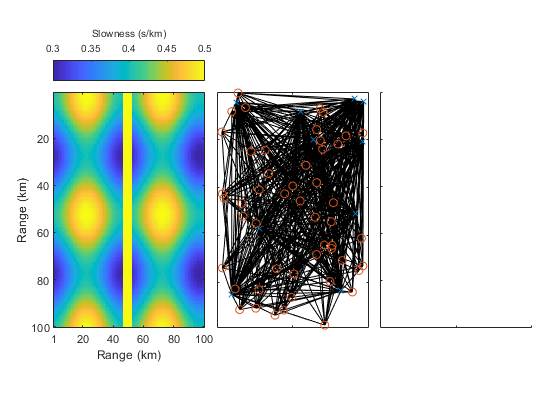

% Step 5: plot figure
figure(1)
%clear current figure
clf  
               %  edge gap   vertical    horizontal
ha=tight_subplot(1,3,[0.01 0.02],[.22 .22],[.095 .05]);

axes(ha(1))
a = ha(1);
pos = get(a,'Position');
imagesc(sTrue,[0.3 0.5])
h=colorbar('northoutside');
set(a,'Position',pos) % fixing image size from colorbar addition
xlabel(h,'Slowness (s/km)')
xlabel('Range (km)')
ylabel('Range (km)')
set(gca,'Xtick',[1,20:20:100])
set(gca,'Ytick',[20:20:100])
axes(ha(2))
% set(gca,'Ydir','reverse')
hold on
for m =1:length(X1)
    plot([X1(m,1),X2(m,1)],[X1(m,2),X2(m,2)],'k')
end
plot(RecLoc(:,1),RecLoc(:,2),'x')
plot(SrcLoc(:,1),SrcLoc(:,2),'o')
axis([1 100 1 100])
hold off
set(gca,'Xticklabel',[])
set(gca,'Yticklabel',[])
box on

% raysPerPix=reshape(sum(A~=0),size(sTrue));% calculating ray density
% % A is 2016x10000, sum(A~=0) summarize the cell along same column
% 
% axes(ha(3))
% a=ha(3);
% pos = get(a,'Position');
% imagesc(log10(raysPerPix))
% h=colorbar('northoutside');
% set(a,'Position',pos) % fixing image size from colorbar addition
% xlabel(h,'Rays per pixel, log_{10} ')
% axis([1 100 1 100])
% hold off
% set(gca,'Xticklabel',[])
% set(gca,'Yticklabel',[])
% box on
B = reshape(Tarr,[LenRec,LenSrc]);
scale_x = floor(SrcLoc(:,1)/(100/Class_dim(1))) + 1; % scale src to range(1,5)
scale_y = floor(SrcLoc(:,2)/(100/Class_dim(2))) + 1; % scale src to range(1,5)
% number of total classes
Class_src = sub2ind(Class_dim, scale_y,scale_x);
Result = [B',Class_src];
% adding header
header = {};
for i = 1:LenRec
    header = [header,['t',int2str(i)]];
end
header = [header,'src_class'];
T = array2table(Result,"VariableNames",header);
writetable(T,filename);